clc;clear;

main_dir = ['/storage08/shuchen/SimulationData/settingSSoS/' ...
    'n500-k10-p_in2btw4-p_out1btw1/' ...
    'r_time0-time_horizon4-r_subject5-num_subjects8/']

main_dir = '/storage08/shuchen/SimulationData/settingSSoS/n500-k10-p_in2btw4-p_out1btw1/r_time0-time_horizon4-r_subject5-num_subjects8/'

% main_dir = 'D:\OneDrive\OneDrive - UW-Madison\Sunduz\SimulationData\settingSSoT\n100-k2-p_in2btw25-p_out1btw1';
% main_dir = 'C:\OneDrive\OneDrive - UW-Madison\Sunduz\SimulationData\settingSSoT\n100-k2-p_in2btw25-p_out1btw1';

samplesTotal = 100;

disp(main_dir);

/storage08/shuchen/SimulationData/settingSSoS/n500-k10-p_in2btw4-p_out1btw1/r_time0-time_horizon4-r_subject5-num_subjects8/


sub_dir = dir(main_dir);
n_rep = 100;
aris_max = zeros([n_rep,1]);
aris_mean = zeros([n_rep,1]);
aris_med = zeros([n_rep,1]);
for i = 3:(n_rep+2)
    i_rep = i-3;
    path = [main_dir, sub_dir(i).name];
    ari_i = load([path,'/aris_ori.mat']).aris;
    ari_sample = mean(ari_i,[1,2]);
    ari_sample = reshape(ari_sample, samplesTotal, 1);
    
    aris_max(i_rep+1) = max(ari_sample);
    aris_mean(i_rep+1) = mean(ari_sample); 
    aris_med(i_rep+1) = median(ari_sample);
end

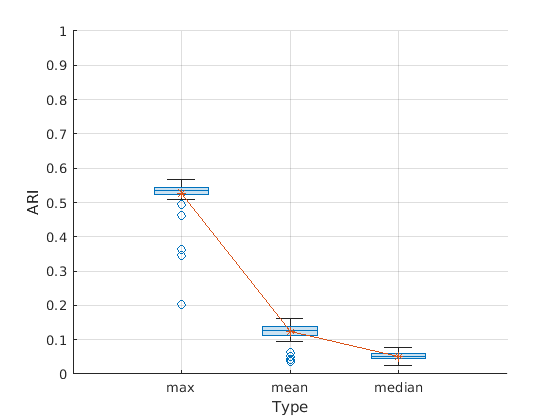

aris3 = [aris_max, aris_mean, aris_med];

figure
boxchart(aris3);         
hold on
grid on
plot(mean(aris3,1),'-*');

xlabel("Type");
ylabel("ARI");
ylim([0,1]);
xticklabels(["max","mean","median"]);